# Population analysis

In this tutorial we cover how to handle models that are fitted separately to different groups of data (i.e. data from different subjects, different sessions or different neurons).

### Declaring a model over a population

The easiest way to run separate regression models for the different groups of observations is to declare the left hand side of the GUM formula as `'y|group ~...'`, where `y` is the dependent variable and `group` is a grouping variable indicating which group each observation belongs to (i.e. subject identity, session identity, ...). We illustrate this below where we will estimate weights separately for each experimental session the monkey perfoms:

T = load_online_dataset();

loading csv file from url...done


M = gum(T, 'resp|session ~ Stimulus + lag(response; Lags=1:5)+0');
M

M = 112x1 GUM object

As you can see, `M `is now an array of GUM objects, with one model for each session.

You can estimate weights from all models at once using the `infer()` method:

M = M.infer('verbose','little');

Inferring weights for model 1/112:  (session=1)*
Inferring weights for model 2/112:  (session=2)*
Inferring weights for model 3/112:  (session=3)*
Inferring weights for model 4/112:  (session=4)*
Inferring weights for model 5/112:  (session=5)*
Inferring weights for model 6/112:  (session=6)*
Inferring weights for model 7/112:  (session=7)*
Inferring weights for model 8/112:  (session=8)*
Inferring weights for model 9/112:  (session=9)*
Inferring weights for model 10/112:  (session=10)*
Inferring weights for model 11/112:  (session=11)*
Inferring weights for model 12/112:  (session=12)*
Inferring weights for model 13/112:  (session=13)*
Inferring weights for model 14/112:  (session=14)*
Inferring weights for model 15/112:  (session=15)*
Inferring weights for model 16/112:  (session=16)*
Inferring weights for model 17/112:  (session=17)*
Inferring weights for model 18/112:  (session=18)*
Inferring weights for model 19/112:  (session=19)*
Inferring weights for model 20/112:  (session=20)

Here for example we can look at the model fitted to session 1:

M(1)

ans = ================================================================================
Generalized Unrestricted Model (GUM) object: unnamed model
resp|session ~ Stimulus + lag(response; Lags=1:5)+0
--------------------------------------------------------------------------------
            Type: GLM (   L2 prior)       Observations:       binomial
 nRegressorBlock:            310     ObservationBlock:              2
   nObservations:            310          isEstimated:            yes
        isFitted:              0              Dataset:       1.000000
     nParameters:             12      nFreeParameters:             12
              df:            298     nFreeHyperparameters:              2
         scaling:       1.000000     SplittingVariable:            NaN
   LogLikelihood:    -128.133031             LogPrior:      -0.113526
        LogJoint:    -128.246557             accuracy:       0.809677
        exitflag:            yes          LogEvidence:    -155.397966
       BIC_infe

**Alternative method: **You can also create an array of models by simply creating each model separately for the corresponding dataset and then use standard concatenation in Matlab, i.e. `M=cat(1,M1, M2, ...);`

### Representing weights and scores over the whole population

You can plot the weights for a specific session using `M(s).plot_weights()`, or plot the weights for all models using `M.plot_weights()`, as below:

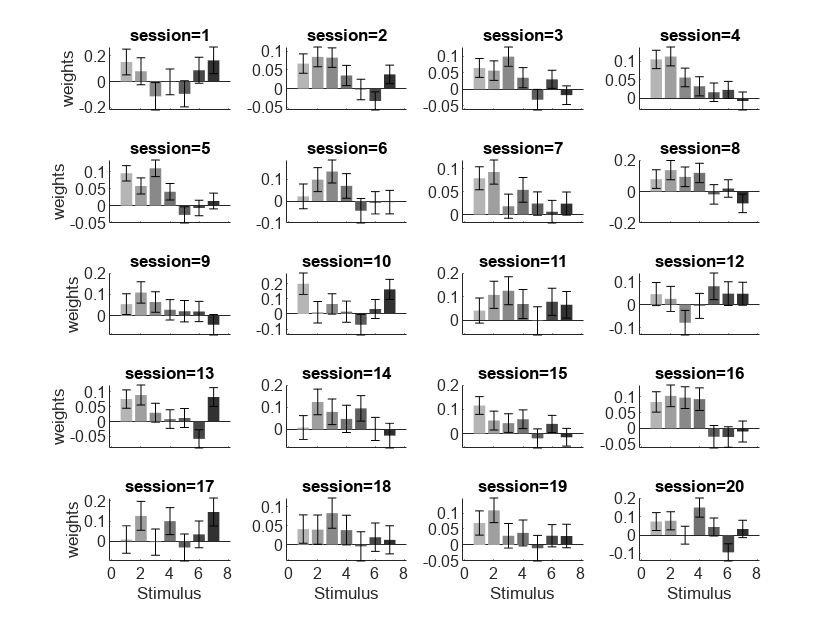

figure;
M(1:20).plot_weights("Stimulus"); % we plot here just for the first 20 sessions

Alternatively, we can plot weights from the different sessions on the same panels by using the `concatenate_over_model()` method. This method will create a scalar GUM object storing the weights from all the different sessions

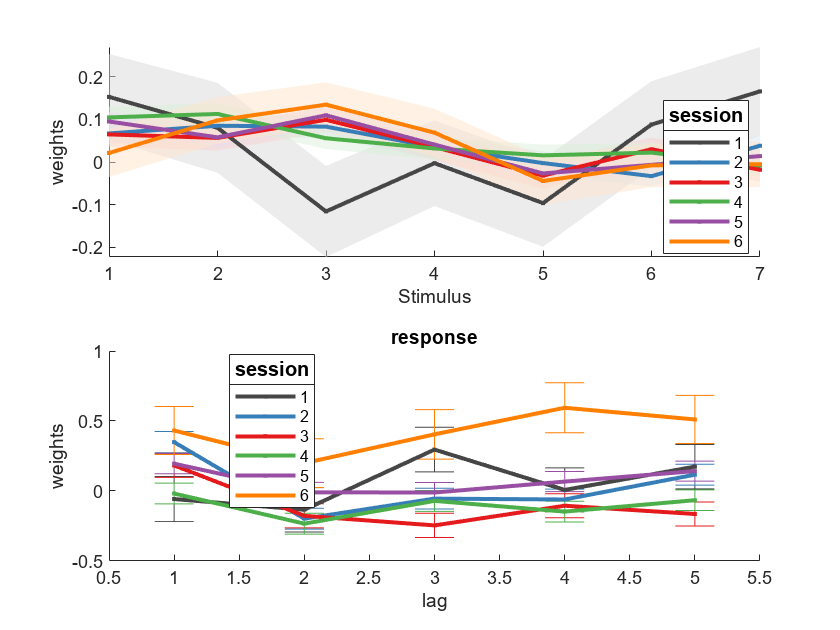

figure; 
% we plot it just for the first 6 sessions
M(1:6).concatenate_over_models.plot_weights;

You can use the `concatenate_over_model() `method to also plot the values of a given model metric (here, model accuracy) across sessions (here in a histogram):

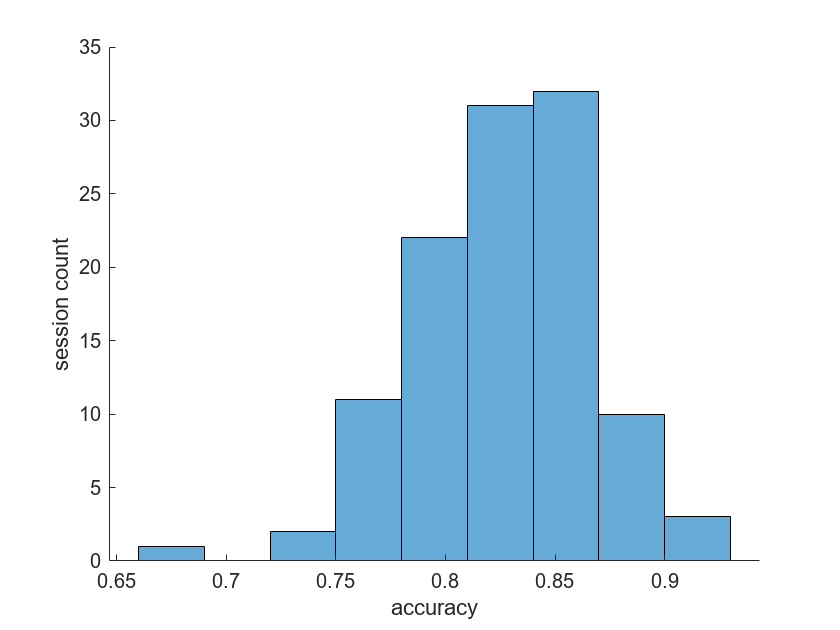

figure;
M.concatenate_over_models.plot_score('accuracy','hist');

You can also export the different metrics for all models as a table or as a csv file using `export_scores_to_table() ` or `export_scores_to_csv()`:

Tscore = M.concatenate_over_models().export_scores_to_table();
head(Tscore)

    nObservations    nParameters     df     Dataset    LogPrior     LogLikelihood    LogJoint    AIC_infer    AICc_infer    BIC_infer    LogEvidence    accuracy    scaling    isEstimated    isFitted    FittingTime
    _____________    ___________    ____    _______    _________    _____________    ________    _________    __________    _________    ___________    ________    _______    ___________    ________    ___________

         310             12

### Population averages

We're often interested in the statistics of the weights across our population. In gum you can compute simply the mean (and standard error of the mean) of the model weights across the population by using the `population_average()` method.

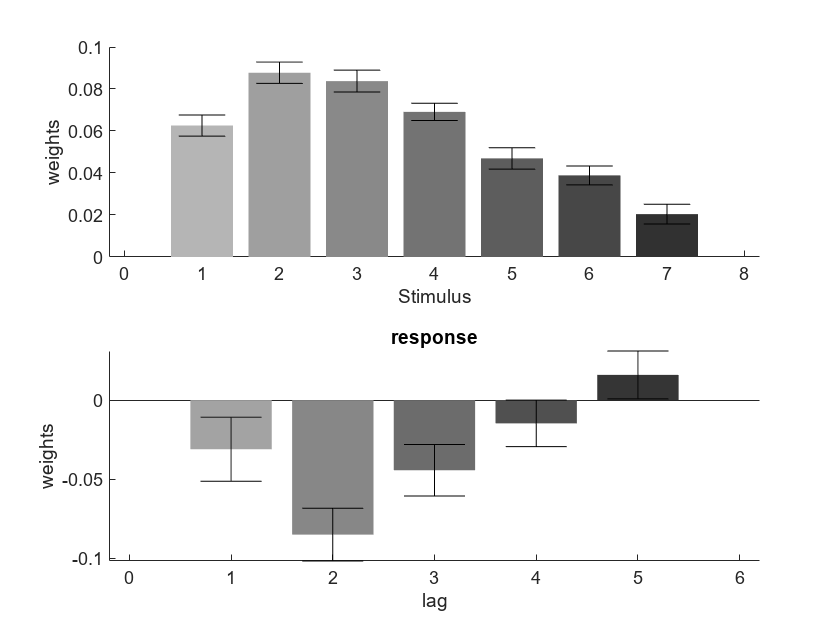

figure;
M.population_average().plot_weights;

By default, the error bars represent the standard error of the mean, but you can switch to the standard deviation using `M.population_average('error','std').`

It is also possible to average weights in different groups using the `'groupby' `option (for example if some sessions correspond to one animal, and the other another animal). Here we plot the weights separately for the first half of the sessions and the second half.

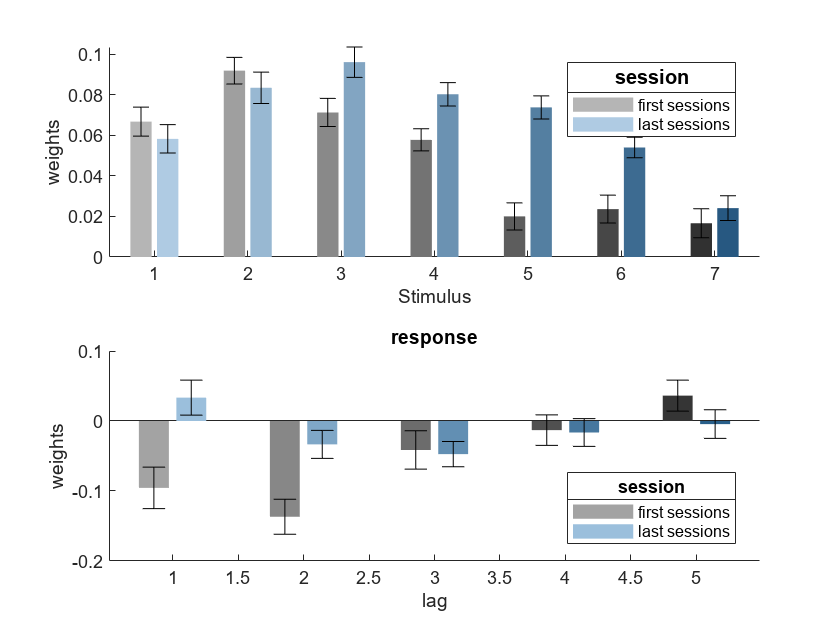

session_group = [ones(1,56) 2*ones(1,56)]; % first sessions: 1, second session: 2
group_id = ["first sessions","last sessions"];
session_group = group_id(session_group); % turn into string array
figure;
M.population_average('groupby',session_group).plot_weights;